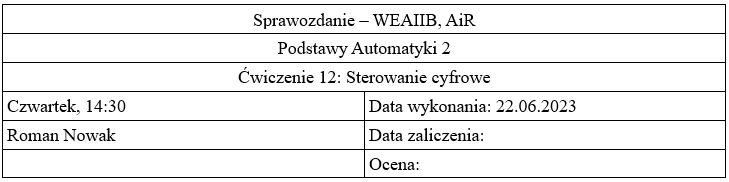

## Cel ćwiczenia

Celem ćwiczenia jest zapoznanie się z budową i działaniem układu regulacji składającego się z ciągłego obiektu regulacji oraz regulatora cyfrowego (dyskretnego). Z taką sytuacją mamy do czynienia w każdej sytuacji, gdy regulator jest zrealizowany na jakiejkolwiek platformie cyfrowej (komputer, sterownik PLC, mikrokontroler, Raspberry Pi, etc). Pomiędzy układami ciągłymi i dyskretnymi występują zarówno analogie, jak i różnice. Podstawowym parametrem układu dyskretnego jest okres próbkowania, określający, jak często odczytywana jest wielkość regulowana z obiektu i wystawiany sygnał sterujący z regulatora na obiekt. Odpowiednikiem transmitancji operatorowej G(s) jest transmitancja dyskretna G(z).

Układ dyskretny jest układem wykorzystującym sygnały (lub sygnał) dyskretne, czyli takie, które przyjmują konkretne wartości tylko w konkretnych chwilach czasu. To jak często te chwile występują określa częstotliwość próbkowania.

Ćwiczenie polegało na zbudowaniu w Simulnku trzech układów regulacji dyskretnej:

- z regulatorem P i obiektem I rzędu

           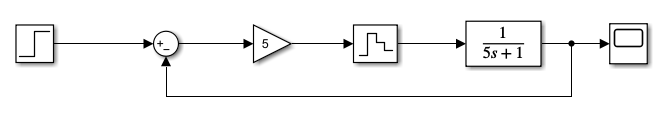

- z regulatorem P i oiektem III rzędu

         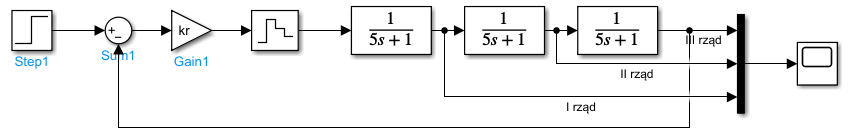

- z regulatorem PID

           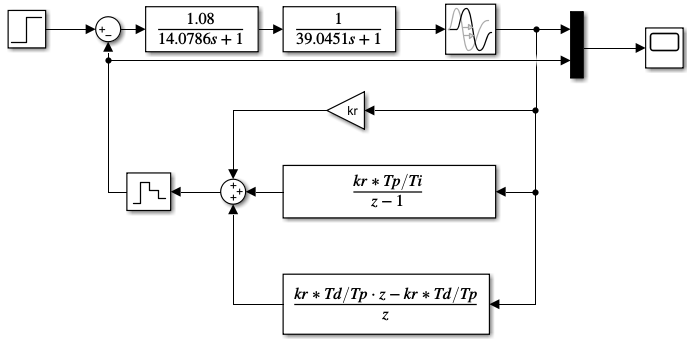

a następnie przetestowaniu przebiegów wartości regulowanej dla różnych wartości okresu próbkowania Tp.

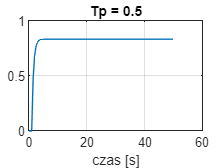

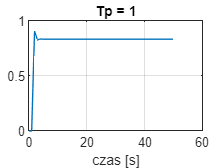

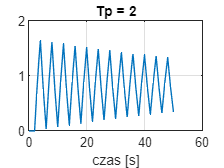

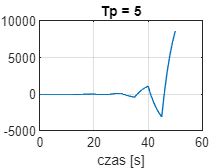

% Parametry symulacji
Tps = [0.5 1 2 5];

for Tp = Tps
    % Symulacja
    out = sim("ster_cyfrowe.slx", 50);
    figure;
    plot(out.P1.time, out.P1.signals.values);
    % opis wykresu
    title("Tp = " + string(Tp));
    grid on;
    xlabel("czas [s]")
end

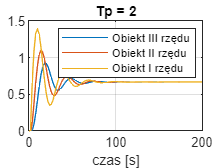

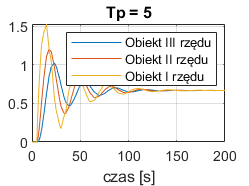

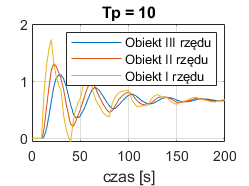

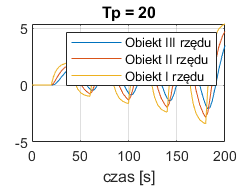

clear;
% Parametry symulacji
kr = 2;
Tps = [2 5 10 20];
for Tp = Tps
    % Symulacja
    out = sim("ster_cyfrowe.slx", 200);
    figure;
    plot(out.P2.time, out.P2.signals.values);
    % opis wykresu
    title("Tp = " + string(Tp));
    legend("Obiekt III rzędu", "Obiekt II rzędu", "Obiekt I rzędu");
    grid on;
    xlabel("czas [s]")
end

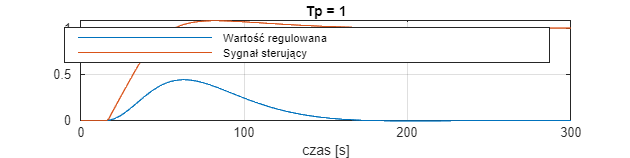

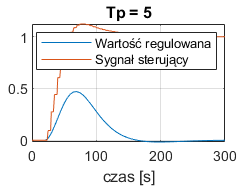

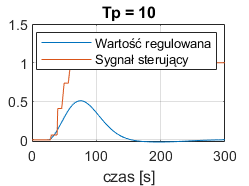

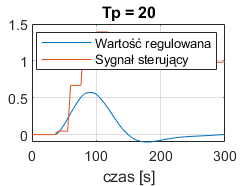

clear;
% Parametry symulacji
kr = 1.5;
Ti = 45;
Td = 11;
Tps = [1 5 10 20];
for Tp = Tps
    % Symulacja
    out = sim("ster_cyfrowe.slx", 300);
    figure;
    plot(out.PID.time, out.PID.signals.values);
    % opis wykresu
    title("Tp = " + string(Tp));
    legend("Wartość regulowana", "Sygnał sterujący");
    grid on;
    xlabel("czas [s]")
end

## Wnioski

- Do wykonania układów regulacji dyskretnej w Simulnku potrzebne były bloki ekstrapolatora i transformaty dyskretnej z.

- W badanych przypadkach, zazwyczaj zwiększenie okresu próbkowania powodowało pogorszenie się stabilności układu. Ostatecznie, nawet w orzypadku obiektu I rzędu z regulatorem P, prowadziło do całkowitej destabilizacji układu

- Okres próbkowania nie może być zbyt duży

- Jedynym regulatorem, dzięki którem udało się uniknąć całkowitej utraty stabilności był regulator PID.